# Generate Skidpad Test

This example shows how to simulate a skidpad test similar to events held in student competitions by Formula Student, Formula SAE, and other organizations internationally. In these, student teams build, operate, and present vehicles of their own design.

In this example, the vehicle starts from rest, then:

- Accelerates to enter the course

- Completes two clockwise laps

- Reverses its steering direction

- Completes two counterclockwise laps

- Exits and brakes to a stop

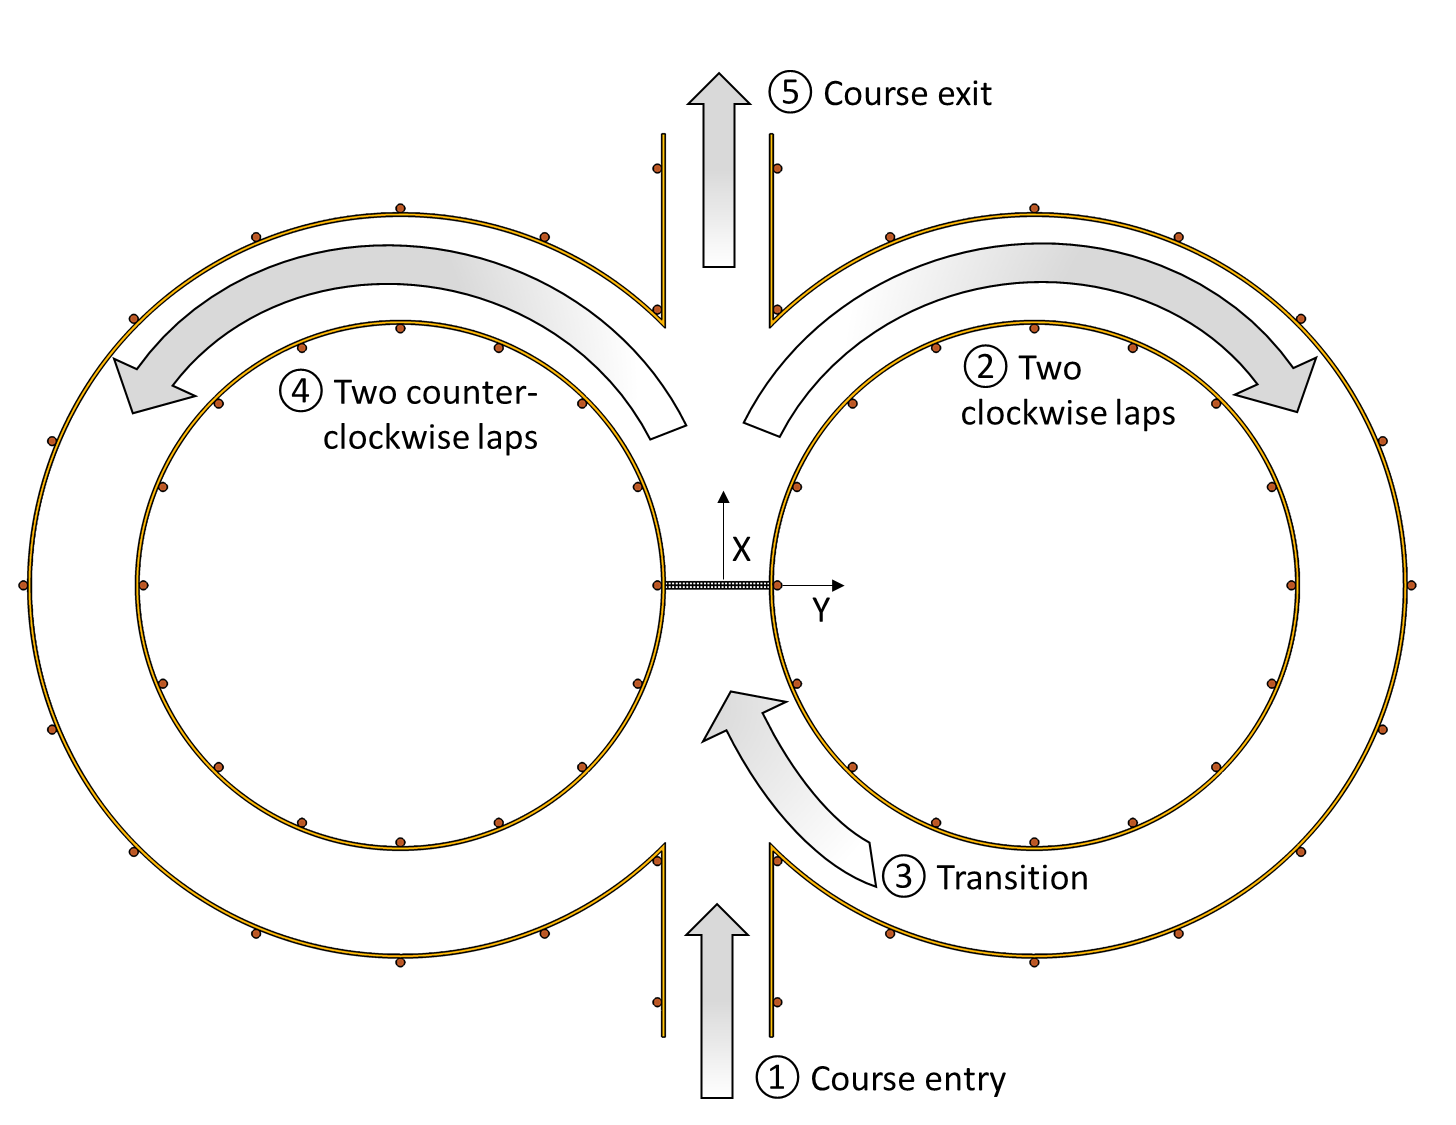

Open Model

The skidpad model includes a reference path, driver, vehicle, and visualization aides. To open the model, use this command.

open_system('vdynblksskidpad');

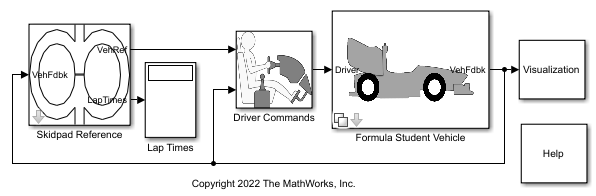

The model workspace variable TrackPoints contains the reference waypoints used to define the reference pose. You can edit or replace them with waypoints of your own. To plot the waypoints, use this code.

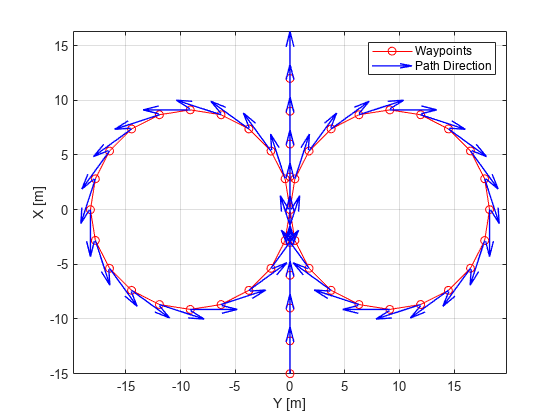

mdlWks = get_param('vdynblksskidpad','ModelWorkspace');
TrackPoints = evalin(mdlWks,'TrackPoints');
figure;
plot(TrackPoints(:,2),TrackPoints(:,1),'ro-')
hold on
arrowLen = 1.5;
quiver(TrackPoints(:,2),TrackPoints(:,1),arrowLen*sin(TrackPoints(:,3)),arrowLen*cos(TrackPoints(:,3)),'b','LineWidth',1,'MaxHeadSize',arrowLen)
box on
grid on
xlabel('Y [m]')
ylabel('X [m]')
axis equal
legend('Waypoints','Path Direction')

The default vehicle path follows the centerline of the course, with some X,Y points duplicated because the vehicle completes multiple laps. You can change factors such as the number of laps or scaling via the blocks found in the Skidpad Reference subsystem. You can also experiment with path points to improve lap times.

Simulate Model

To run the model and observe the vehicle completing the course, use this command.

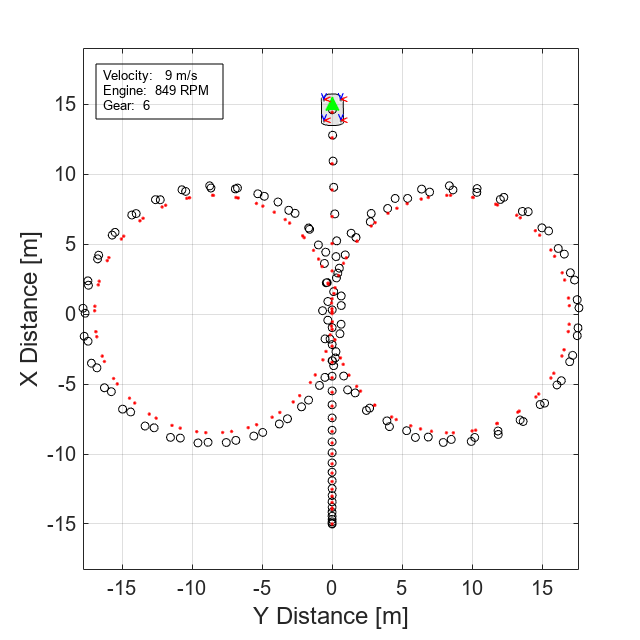

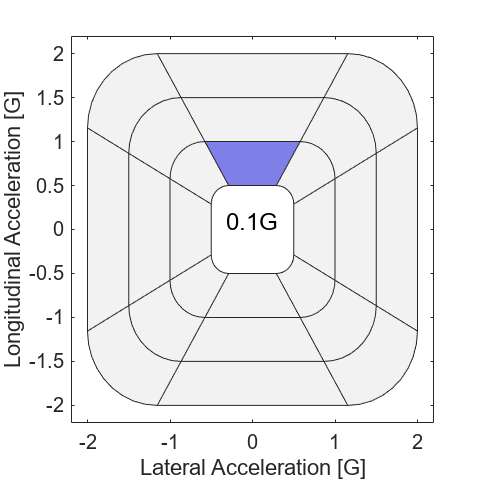

sim('vdynblksskidpad');

By default, an overhead figure depicting the reference and simulated vehicle path, and acceleration diagram are opened and updated during simulation. Lap times are estimated and displayed in order at the top level of the model via a Display block.

You can model the vehicle as either of two variant subsystems, using blocks from the **Vehicle Dynamics Blockset** library: Simulink Physics or Game Engine Physics. To set the vehicle type, double-click the Formula Student Vehicle block and select from the Vehicle Type list. To set the vehicle type programmatically, use the `set_param` command.

By default, the Simulink Physics setting uses a 7DOF vehicle containing multiple subsystems and components, including an ideal powertrain, driveline, tires, and chassis. The Game Engine Physics setting has similar parameters but uses a simulation 3D interface to configure and solve for the dynamic response of the predefined vehicle template. Given the differences in tire models and solver engines between the two settings, differences in results are to be expected. Choose your setting based on your modeling and visualization preferences.

Use this command to set the model to use the game engine vehicle.

vehType = "Game Engine Physics"

vehType = "Game Engine Physics"

% set_param( 'vdynblksskidpad/Formula Student Vehicle','vehType',vehType);

Enable 3D Visualization

Before running the model in the 3D visualization environment, review the [Unreal Engine Simulation Environment Requirements and Limitations](docid:vdynblks_ug#mw_d93f6fdf-3a25-4ced-abcb-0782c74d97e4). To enable the 3D visualization, use these commands.

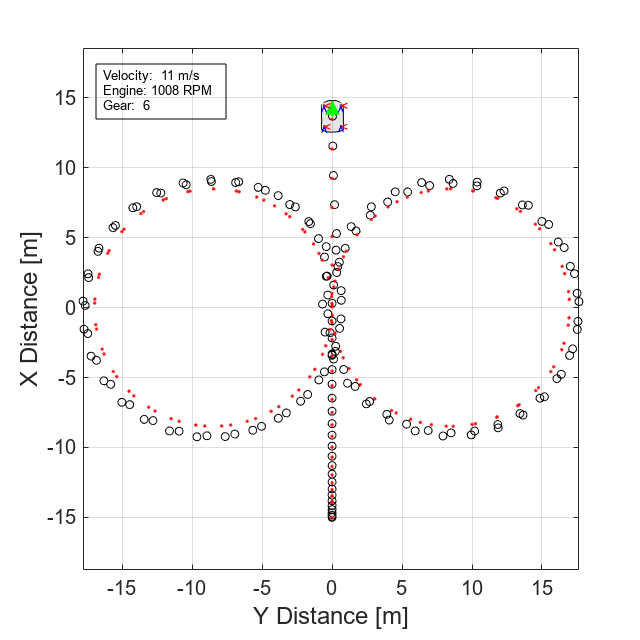

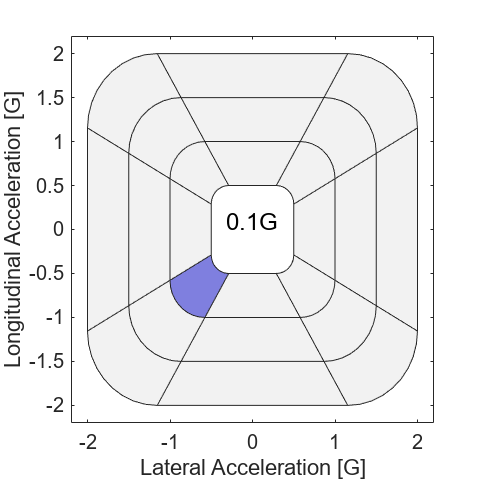

 set_param('vdynblksskidpad/Visualization/3D Visualization','engine3D','Enabled - Simulink 3D Vehicle')
 set_param('vdynblksskidpad/Visualization/3D Visualization','conesOn','on');
 sim('vdynblksskidpad');

You can also place cones with Simulink 3D Animation to better define the skid pad course when using the 3D visualization engine. You can adjust cone placement through the initialization script in the Simulation 3D Actor block.

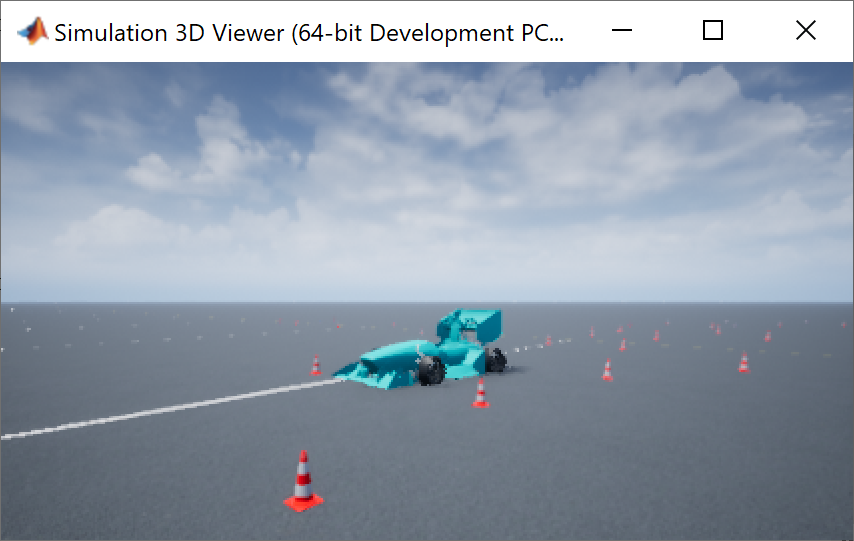

*Copyright 2022 The MathWorks, Inc*.